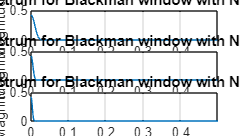


N_values = [100, 200, 300];
DFT_size = 1024;

frequencies = linspace(0, 1, DFT_size);
for i = 1:length(N_values)
    N = N_values(i);
    blackman_window = blackman(N)';
    padded_window = [blackman_window, zeros(1, DFT_size - N)];
    window_dft = fft(padded_window, DFT_size);
    normalized_magnitude = abs(window_dft) / N;
    subplot(length(N_values), 1, i);
    plot(frequencies, normalized_magnitude);
    title(['Spectrum for Blackman window with N = ', num2str(N)]);
    xlabel('Normalized Frequency');
    ylabel('Magnitude');
    xlim([0, 0.5]); 
    grid on;
end


set(gcf, 'Position', get(0, 'Screensize'));

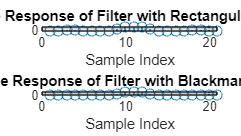


alpha = 2; 
cutoff_frequency = pi / (alpha + 1);
window_length = 21;
rectangular_window = ones(1, window_length);
rectangular_filter = fir1(window_length - 1, cutoff_frequency / pi, 'low', rectangular_window);
blackman_window = blackman(window_length)';
blackman_filter = fir1(window_length - 1, cutoff_frequency / pi, 'low', blackman_window);
figure;
hold on
subplot(2, 1, 1);
stem(rectangular_filter);
title('Impulse Response of Filter with Rectangular Window');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
stem(blackman_filter);
title('Impulse Response of Filter with Blackman Window');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;
hold off
set(gcf, 'Position', get(0, 'Screensize'));

% 2. Frequency response analysis (Bode plot)
[rectangular_filter_response, rectangular_filter_freq] = freqz(rectangular_filter, 1, 'half', 1024);
[blackman_filter_response, blackman_filter_freq] = freqz(blackman_filter, 1, 'half', 1024);

hold on

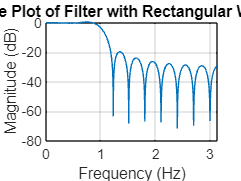

figure;
%subplot(2, 1, 1);
plot(rectangular_filter_freq, 20*log10(abs(rectangular_filter_response)));
title('Bode Plot of Filter with Rectangular Window');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

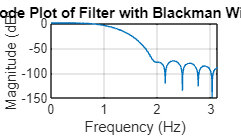


%subplot(2, 1, 2);
plot(blackman_filter_freq, 20*log10(abs(blackman_filter_response)));
title('Bode Plot of Filter with Blackman Window');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
hold off

set(gcf, 'Position', get(0, 'Screensize'));

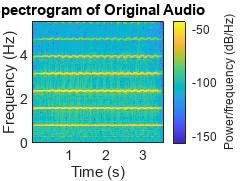

filename = 'instru2.wav';
[y, Fs] = audioread(filename);
figure;
spectrogram(y, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Original Audio');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

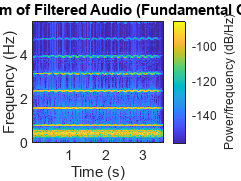



fundamental_frequency = 440; 
nyquist_frequency = Fs / 2;
filter_order = 100; 


filter_frequency = [fundamental_frequency - 10, fundamental_frequency + 10] / nyquist_frequency;
fir_filter = fir1(filter_order, filter_frequency, 'bandpass', hamming(filter_order + 1));
filtered_audio = filter(fir_filter, 1, y);
figure;
spectrogram(filtered_audio, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Filtered Audio (Fundamental Only)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

output_filename = 'filtered_audio.wav';
audiowrite(output_filename, filtered_audio, Fs);

%disp('Playing Filtered Audio...');
sound(filtered_audio, Fs);

disp(['Filtered audio saved as ', output_filename]);

Filtered audio saved as filtered_audio.wav
